# **Session 1: Working with an existing data pipeline with DataJoint**

This live scripts introduce how to work with an existing data pipeline, we will cover the following topics:

- Check schema structure and table definitions

- Flexible queries

- Fetching from query results

## Schema structure and table definitions

Schemas are groups of tables that are intuitively related. In the U19 pipeline, we have the following schemas:

- lab: the lab schema contains general information of the lab

- subject: the subject schema contains information about the animals

- action: the action schema contains water, weighing, and action item information

- acquisition: the acquisition schema contains behavioral information, and also the scanning information of the two-photon recording

- behavior: the imaging schema contains the processing steps of the behavioral experiments.

To check the schema structure, we could use `erd` to draw a diagram

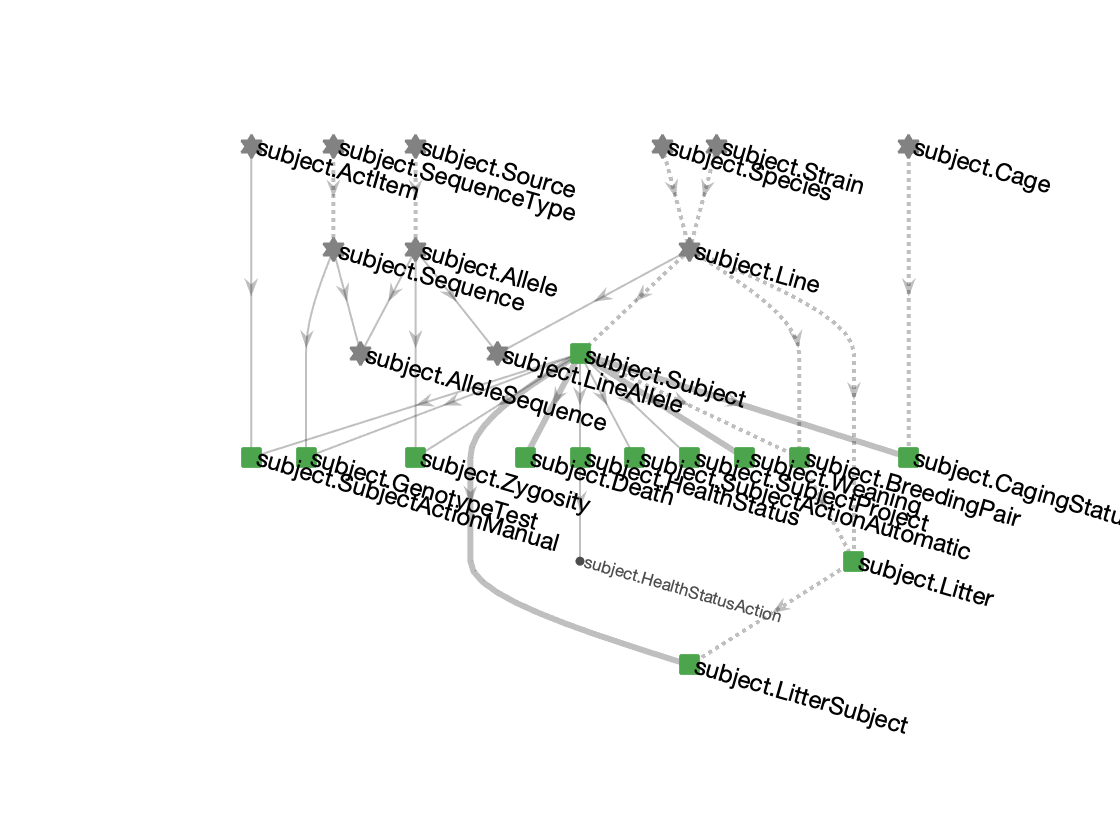

erd subject

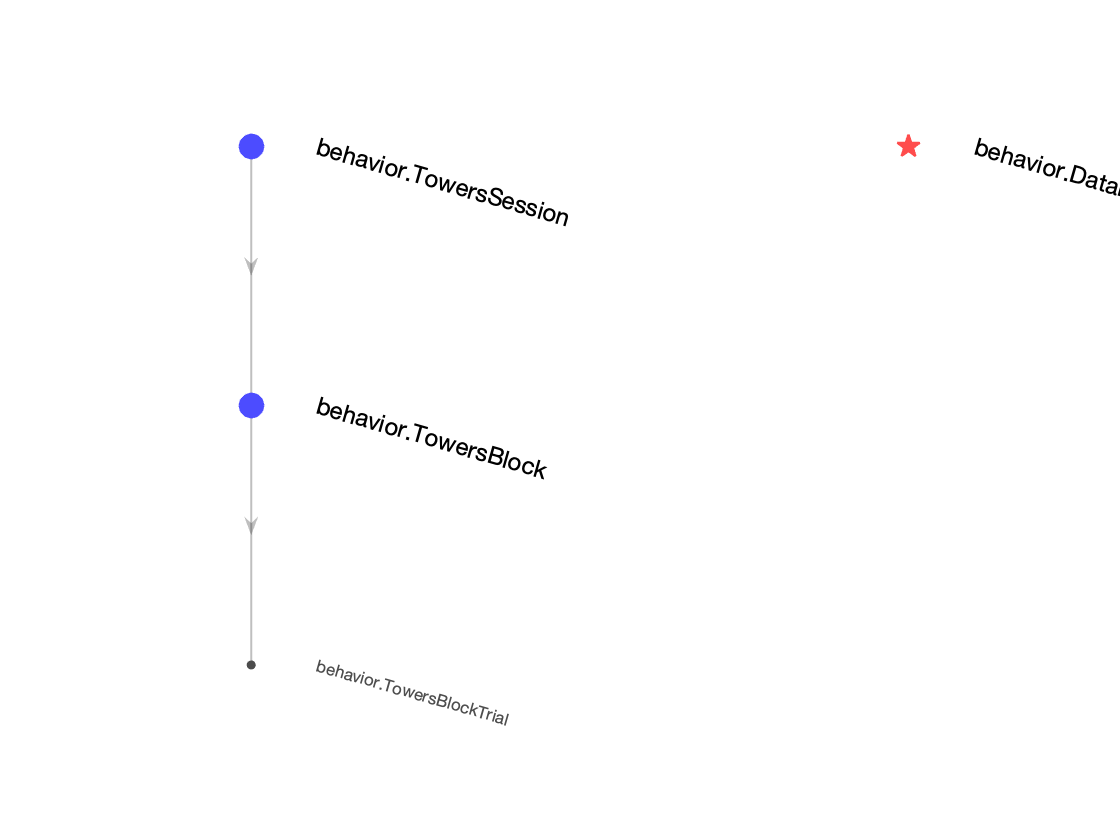

erd behavior

There are five types of tables:

- Manual tables (green squares): tables for manual information, such as Subject, lost if deleted

- Lookup tables (gray stars): tables for general information, such as some parameter settings

- Imported tables (blue dots): tables that are ingested from external files, such as recording tiff files from two-photon imaging, allowing auto-populate. When deleted, the entries were recoverable if the external files still exist.

- Computed tables (red stars): tables that are computed from tables within the database, allow auto-populate. Easily recoverable when the entries are deleted.

- Part tables (gray little dots): allow insertion by their master tables.

There are three types of table dependencies:

- One to one: child table and its parent table has the exact same primary key.

- One to many: other than the primary key of the parent table, the child table has some other fields as part of primary key

- Secondary attribute dependency: a secondary attribute is a field of the primary key of another table

- Many to many: implemented with two one-to-many dependencies

We could use `describe` to check a table definition. The --- separates the primary key and secondary attributes, -> indicates a dependency to its parent table. For example, the table subject.Subject has a one-to-many dependency with its parent table lab.User

describe(subject.Subject)

ans =     '%{
     # 
     subject_fullname            : varchar(64)                   # username_mouse_nickname
     ---
     subject_nickname            : varchar(16)                   # 
     -> `u19_lab`.`user`
     genomics_id=null            : int                           # number from the facility
     sex="Unknown"               : enum('Male','Female','Unknown') # sex
     dob=null                    : date                          # birth date
     head_plate_mark=null        : blob                          # little drawing on the head plate for mouse identification
     -> `u19_lab`.`#location`
     -> `u19_lab`.`#protocol`
     -> subject.Line
     subject_description         : varchar(255)                  # description
     initial_weight=null         : float                         # 
     %}
     '


We could also directly print out a table to get an overview of the table contents, the primary key columns are CAPITALIZED

subject.Subject

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id      genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________________    ________________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'emanuele_B205'     'B205'              'emanuele'    NaN            'Male'    ''     'vivarium'    '1910'      'DAT-IRES-CRE'    ''                     27           

Another example, 

action.Weighing

ans = Object action.Weighing

 ::  ::

    SUBJECT_FULLNAME        WEIGHING_TIME        weigh_person       location        weight
    ________________    _____________________    ____________    _______________    ______

    'emanuele_B205'     '2018-06-20 12:52:00'    'emanuele'      'pni-174cr4jk2'      26  
    'emanuele_B205'     '2018-06-21 16:53:00'    'emanuele'      'pni-174cr4jk2'    25.5  
    'emanuele_B205'     '2018-06-23 04:39:00'    'emanuele'      'pni-174cr4jk2'      25  
    'emanuele_B205'     '2018-06-24 21:22:00'    'emanuele'      'pni-174cr4jk2'      26  
    'emanuele_B205'     '2018-06-25 15:15:00'    'emanuele'      'pni-174cr4jk2'    25.7  
    'emanuele_B205'     '2018-06-27 11:55:00'    'emanuele'      'pni-174cr4jk2'      26  
    'emanuele_B205'     '2018-06-28 12:44:00'    'emanuele'   

## Flexible Queries

DataJoint supports powerful but intuitive queries. We will list a few important ones:

- Restriction (filter): & or -, filter the entries with some criteria.

- Join: *, gather fields together from different tables.

- proj(): only focus on a subset of secondary attribute, rename field and simple computation

- aggr(): simple computations on one against some other tables

## Restrictions (Filters)  & takes multiple forms

% restrictor as a string
subject.Subject & 'user_id = "lpinto"'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id     genomics_id      sex           dob          location     protocol        line        subject_description    initial_weight    head_plate_mark
    ________________    ________________    ________    ___________    ________    ____________    __________    ________    ____________    ___________________    ______________    _______________

    'lpinto_ai10'       'ai10'              'lpinto'    NaN            'Male'      '2017-11-08'    'vivarium'    '1910'      'Ai93-Emx1'     ''             

% restrictor as a string, unequal
subject.Subject & 'dob > "2019-01-01"'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id     genomics_id      sex           dob          location     protocol          line          subject_description    initial_weight    head_plate_mark
    ________________    ________________    ________    ___________    ________    ____________    __________    ________    ________________    ___________________    ______________    _______________

    'lpinto_SP1'        'SP1'               'lpinto'    NaN            'Female'    '2019-03-27'    'vivarium'    '1910'      'Unknown'           '' 

% restrictor as a string, within a range
subject.Subject & 'dob between "2019-01-01" and "2019-02-01"'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id      genomics_id      sex           dob          location     protocol               line                subject_description    initial_weight    head_plate_mark
    ________________    ________________    __________    ___________    ________    ____________    __________    ________    ___________________________    ___________________    ______________    _______________

    'mioffe_M5_696'     'M5_696'            'mioffe'      NaN            'Female'    '2019-01-21'    'vivarium'    '1910' 

% restrictor as a string, "or" 
subject.Subject & 'sex in ("Male", "Female")'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id      genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________________    ________________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'emanuele_B205'     'B205'              'emanuele'    NaN            'Male'    ''     'vivarium'    '1910'      'DAT-IRES-CRE'    ''                     27           

% restrictor as a string, "or" 
subject.Subject & 'sex = "Male" or sex = "Female"'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id      genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________________    ________________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'emanuele_B205'     'B205'              'emanuele'    NaN            'Male'    ''     'vivarium'    '1910'      'DAT-IRES-CRE'    ''                     27           

For more syntax of restrictors as a string, check on MYSQL syntax. DataJoint supports most of the MYSQL syntax.

DataJoint also takes a struct as a restrictor:

subject.Subject & struct('user_id', 'lpinto', 'sex', 'Male')

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id     genomics_id     sex          dob          location     protocol         line          subject_description    initial_weight    head_plate_mark
    ________________    ________________    ________    ___________    ______    ____________    __________    ________    _______________    ___________________    ______________    _______________

    'lpinto_ai10'       'ai10'              'lpinto'    NaN            'Male'    '2017-11-08'    'vivarium'    '1910'      'Ai93-Emx1'        ''          

Retrictor as a array of struct perform the 'or' logic.

subject.Subject & [struct('user_id', 'lpinto', 'sex', 'Male'), struct('user_id', 'hnieh', 'sex', 'Male')]

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id    genomics_id     sex      dob     location     protocol      line       subject_description    initial_weight    head_plate_mark
    ________________    ________________    _______    ___________    ______    ___    __________    ________    _________    ___________________    ______________    _______________

    'hnieh_E18'         'E18'               'hnieh'    NaN            'Male'    ''     'valhalla'    '1910'      'Unknown'    ''                       26              '=BLOB='       
   

Restrict with other tables.

All mice that have a session

subject.Subject & acquisition.Session

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id      genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    head_plate_mark
    ________________    ________________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    _______________

    'emanuele_B205'     'B205'              'emanuele'    NaN            'Male'    ''     'vivarium'    '1910'      'DAT-IRES-CRE'    ''                     27           

All mice that don't have a session

subject.Subject - acquisition.Session

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id     genomics_id      sex           dob          location     protocol        line        subject_description    initial_weight    head_plate_mark
    ________________    ________________    ________    ___________    ________    ____________    __________    ________    ____________    ___________________    ______________    _______________

    'hnieh_E42'         'E42'               'hnieh'     NaN            'Male'      ''              'vivarium'    '1910'      'Unknown'       ''             

All forms of restrictors could be combined:

subject.Subject & [struct('user_id', 'koay', 'sex', 'Male'), struct('user_id', 'hneih', 'sex', 'Male')] & 'subject_nickname="K62"'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id    genomics_id     sex      dob     location     protocol       line        subject_description    initial_weight    head_plate_mark
    ________________    ________________    _______    ___________    ______    ___    __________    ________    ___________    ___________________    ______________    _______________

    'koay_K62'          'K62'               'koay'     NaN            'Male'    ''     'vivarium'    '1910'      'Ai93-Emx1'    ''                     22.5              '=BLOB='     

## Join `*` gathers fields from different tables together

subject.Subject * action.WaterAdministration

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME    ADMINISTRATION_DATE    subject_nickname     user_id      genomics_id     sex      dob     location     protocol         line         subject_description    initial_weight    earned    supplement    received    watertype_name    head_plate_mark
    ________________    ___________________    ________________    __________    ___________    ______    ___    __________    ________    ______________    ___________________    ______________    <

## Projection `proj(`) only keeps a subset of the secondary attributes

No arguments:

% with no arguments it only keeps the primary key
subject.Subject().proj()

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME
    ________________

    'emanuele_B205' 
    'emanuele_B208' 
    'emanuele_B3151'
    'emanuele_B4486'
    'emanuele_B4487'
    'emanuele_B4488'
    'emanuele_B4489'
    'hnieh_E18'     
    'hnieh_E26'     
    'hnieh_E36'     
    'hnieh_E38'     
    'hnieh_E39'     

          ...

191 tuples (0.0975 s)


It also works like this.

proj(subject.Subject)

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME
    ________________

    'emanuele_B205' 
    'emanuele_B208' 
    'emanuele_B3151'
    'emanuele_B4486'
    'emanuele_B4487'
    'emanuele_B4488'
    'emanuele_B4489'
    'hnieh_E18'     
    'hnieh_E26'     
    'hnieh_E36'     
    'hnieh_E38'     
    'hnieh_E39'     

          ...

191 tuples (0.0632 s)


Actually this is more commonly used because adding filters to this is easy.

proj(subject.Subject & 'user_id="lpinto"')

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME
    ________________

    'lpinto_ai10'   
    'lpinto_ai11'   
    'lpinto_ai12'   
    'lpinto_ai13'   
    'lpinto_ai7'    
    'lpinto_ai8'    
    'lpinto_ai9'    
    'lpinto_GP1'    
    'lpinto_GP2'    
    'lpinto_GP3'    
    'lpinto_GP4'    
    'lpinto_GP5'    

          ...

74 tuples (0.0566 s)


Now keep some other attributes as well:

proj(subject.Subject, 'dob', 'sex')

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME     sex      dob
    ________________    ______    ___

    'emanuele_B205'     'Male'    '' 
    'emanuele_B208'     'Male'    '' 
    'emanuele_B3151'    'Male'    '' 
    'emanuele_B4486'    'Male'    '' 
    'emanuele_B4487'    'Male'    '' 
    'emanuele_B4488'    'Male'    '' 
    'emanuele_B4489'    'Male'    '' 
    'hnieh_E18'         'Male'    '' 
    'hnieh_E26'         'Male'    '' 
    'hnieh_E36'         'Male'    '' 
    'hnieh_E38'         'Male'    '' 
    'hnieh_E39'         'Male'    '' 

          ...

191 tuples (0.0767 s)


`proj()` also allows renaming the fields

proj(subject.Subject, 'dob->birth_date', 'sex')

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME     sex      birth_date
    ________________    ______    __________

    'emanuele_B205'     'Male'    ''        
    'emanuele_B208'     'Male'    ''        
    'emanuele_B3151'    'Male'    ''        
    'emanuele_B4486'    'Male'    ''        
    'emanuele_B4487'    'Male'    ''        
    'emanuele_B4488'    'Male'    ''        
    'emanuele_B4489'    'Male'    ''        
    'hnieh_E18'         'Male'    ''        
    'hnieh_E26'         'Male'    ''        
    'hnieh_E36'         'Male'    ''        
    'hnieh_E38'         'Male'    ''        
    'hnieh_E39'         'Male'    ''        

          ...

191 tuples (0.104 s)


and some simple computations:

Example 1: get the date of a weighing

proj(action.Weighing & 'subject_id="B205"', 'date(weighing_time)->weighing_date')

q = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME    SESSION_DATE    SESSION_NUMBER        dob     
    ________________    ____________    ______________    ____________

    'hnieh_E58'         '2017-10-17'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-18'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-19'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-20'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-23'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-24'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-25'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-26'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-27'    0                 '2016-11-14'
    'hnieh_E58'         '2017-10-31'    0   

Example 2: What is the age of an animal when performing each session?

% First get the date of birth and the session date into the same query
q = subject.Subject().proj('dob') * acquisition.Session().proj() & 'dob != ""'

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME    SESSION_DATE    SESSION_NUMBER    age_in_days
    ________________    ____________    ______________    ___________

    'hnieh_E58'         '2017-10-17'    0                 337        
    'hnieh_E58'         '2017-10-18'    0                 338        
    'hnieh_E58'         '2017-10-19'    0                 339        
    'hnieh_E58'         '2017-10-20'    0                 340        
    'hnieh_E58'         '2017-10-23'    0                 343        
    'hnieh_E58'         '2017-10-24'    0                 344        
    'hnieh_E58'         '2017-10-25'    0                 345        
    'hnieh_E58'         '2017-10-26'    0                 346        
    'hnieh_E58'         '2017-10-27'    0                 347        
    'hnieh_E58'         '2017-10-31'    0            

% Then perform the computation with proj()
q.proj('datediff(session_date, dob)->age_in_days')

ans = Object dj.internal.GeneralRelvar

     USER_ID      n_animals
    __________    _________

    'baptista'     1       
    'emanuele'     7       
    'hnieh'       50       
    'joelcf'       1       
    'jteran'       1       
    'koay'        19       
    'lpinto'      74       
    'lteachen'     1       
    'mioffe'      21       
    'sbolkan'      1       
    'ss31'         1       
    'testuser'    17       

          ...

13 tuples (0.583 s)


 Aggregation `.aggr()`: simple computation of one table against another table

Example: how many animals does each user have?

lab.User().aggr(subject.Subject, 'count(*)->n_animals')

ans = 191×1 struct array with fields:
    subject_fullname


## Fetching data

So far, we have been querying from the database, but did not get any data fetched, in the form of matlab data types. We could fetch from **any query** we performed so far. With the syntax `fetch(query, ...)` or `query.fetch(...)`

Fetch everything from a table: get an structure array of primary keys

subject.Subject().fetch()

Fetch specific fields, but still as an array of struct

subjects_stats = subject.Subject().fetch('*')

ans = 22

Everything you get with `fetch()` is an array of sturct, with the primary keys, even if you only have one entry. If you want other data formats to return without the primary key, here are two other options:

- fetch1(): works on queries only with one entry

- fetchn(): works on any queries

fetch1(subject.Subject & 'subject_nickname="E70"', 'initial_weight')

ans = 191×1 cell array
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {0×0 char    }
    {'2016-11-14'}
    {0×0 char    }
    {'2017-07-27'}
    {'2017-07-27'}
    {'2017-04-02'}
    {'2017-07-27'}
    {'2017-07-27'}
    {'2017-06-15'}
    {'2017-11-20'}
    {'2018-01-18'}
    {'2018-01-18'}
    {'2017-11-20'}
    {'2017-11-20'}
    {'2017-12-13'}
    {'2017-12-13'}
    {'2018-03-25'}
    {'2017-11-08'}
    {'2017-11-08'}
    {'2017-05-03'}
    {0×0 char    }
    {'2018-10-24'}
    {'2018-10-24'}
    {'2018-10-24'}
    {'2018-10-08'}
    {0×0

fetchn(subject.Subject & 'subject_nickname="E70"', 'initial_weight')

dob = '2017-12-13'

sex = 'Male'

initial_weight = 30

fetchn(subject.Subject, 'dob')

subj = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id    genomics_id     sex          dob          location     protocol        line        subject_description    initial_weight    head_plate_mark
    ________________    ________________    _______    ___________    ______    ____________    __________    ________    ____________    ___________________    ______________    _______________

    'hnieh_E74'         'E74'               'hnieh'    NaN            'Male'    '2017-12-13'    'vivarium'    '1910'      'Thy1-GP5.3'    ''                     

Fetch multiple fields at the same time, individually

[dob, sex, initial_weight] = fetch1(subject.Subject & 'subject_nickname="E74"', 'dob', 'sex', 'initial_weight')

subj_key = struct with fields:
    subject_fullname: 'hnieh_E74'


subj = subject.Subject & 'subject_nickname="E74"'
subj_key = subj.fetch()
[water_date, earned_water] = fetchn(action.WaterAdministration & subj_key, 'administration_date', 'earned');

Earned water as a function of date.

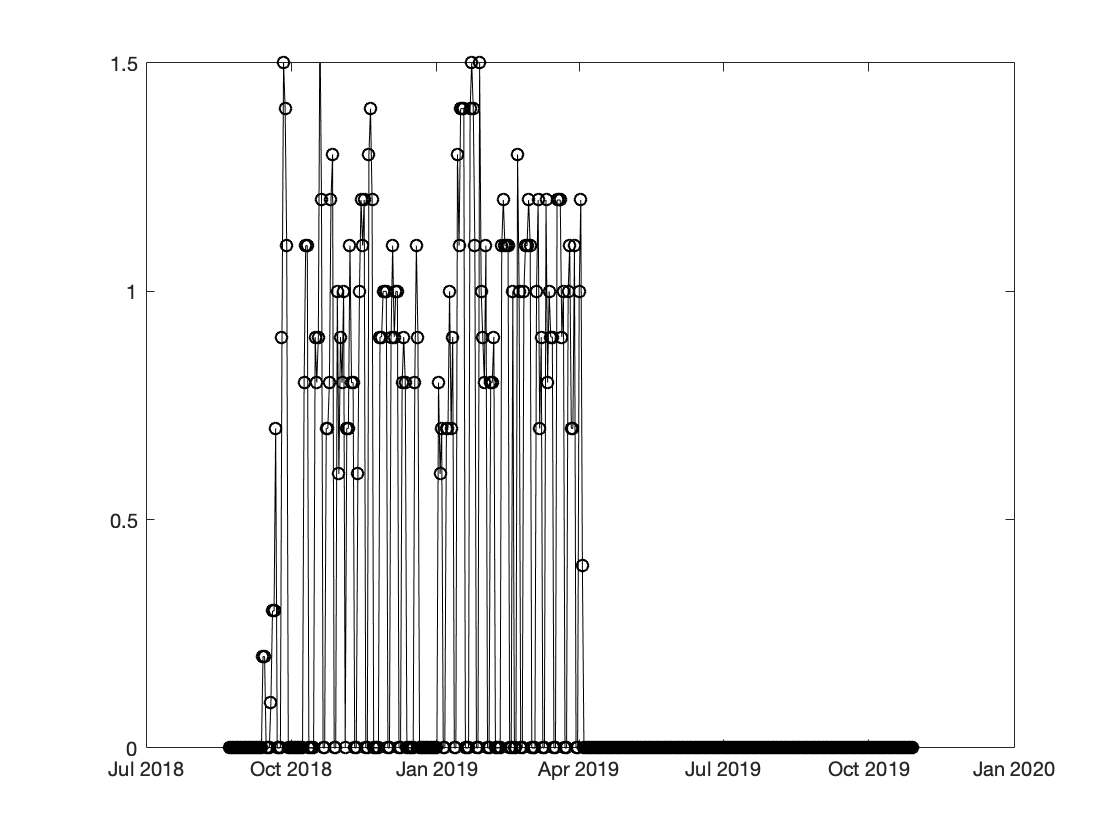

water_date = datetime(water_date);
figure; plot(water_date, earned_water, 'ko-')
ylim([0, 1.5])

Weight as a function of date.

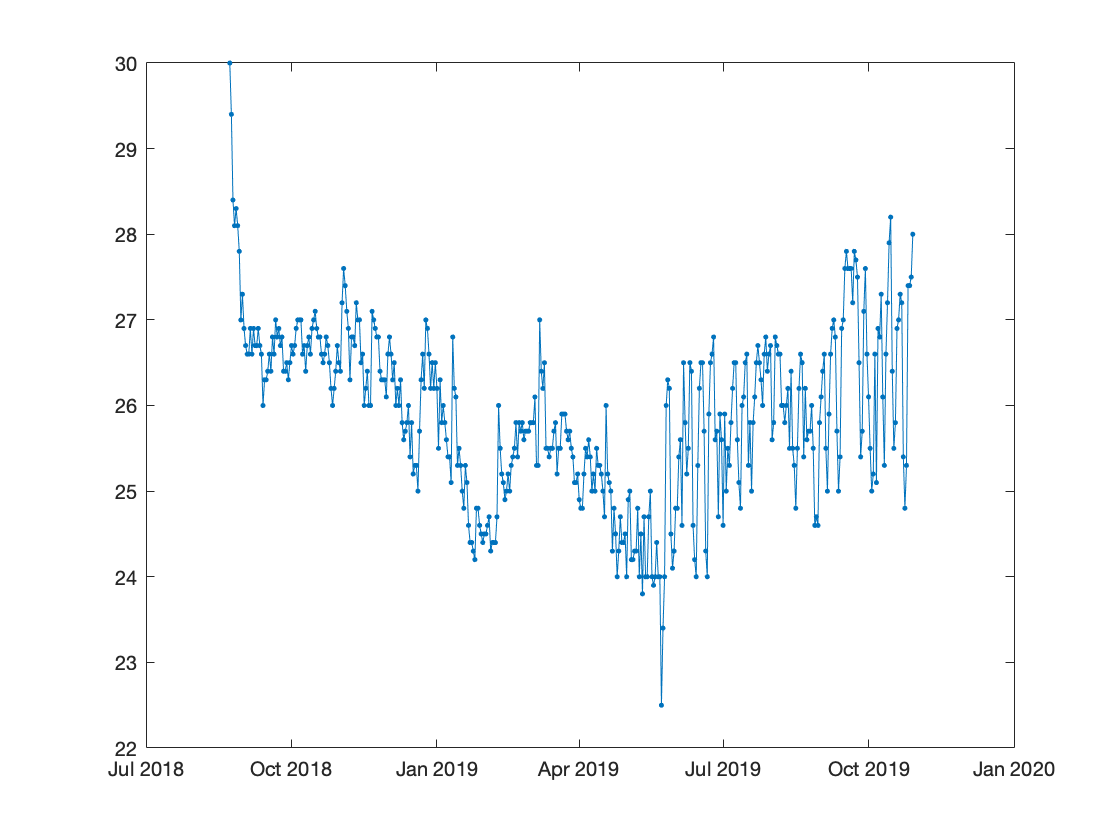

[weighing_date, weight] = fetchn(...
    action.Weighing & subj_key, 'DATE(weighing_time)->weighing_date', 'weight');
weighing_date = datetime(weighing_date);
figure; plot(weighing_date, weight, '.-')

Plot both together:

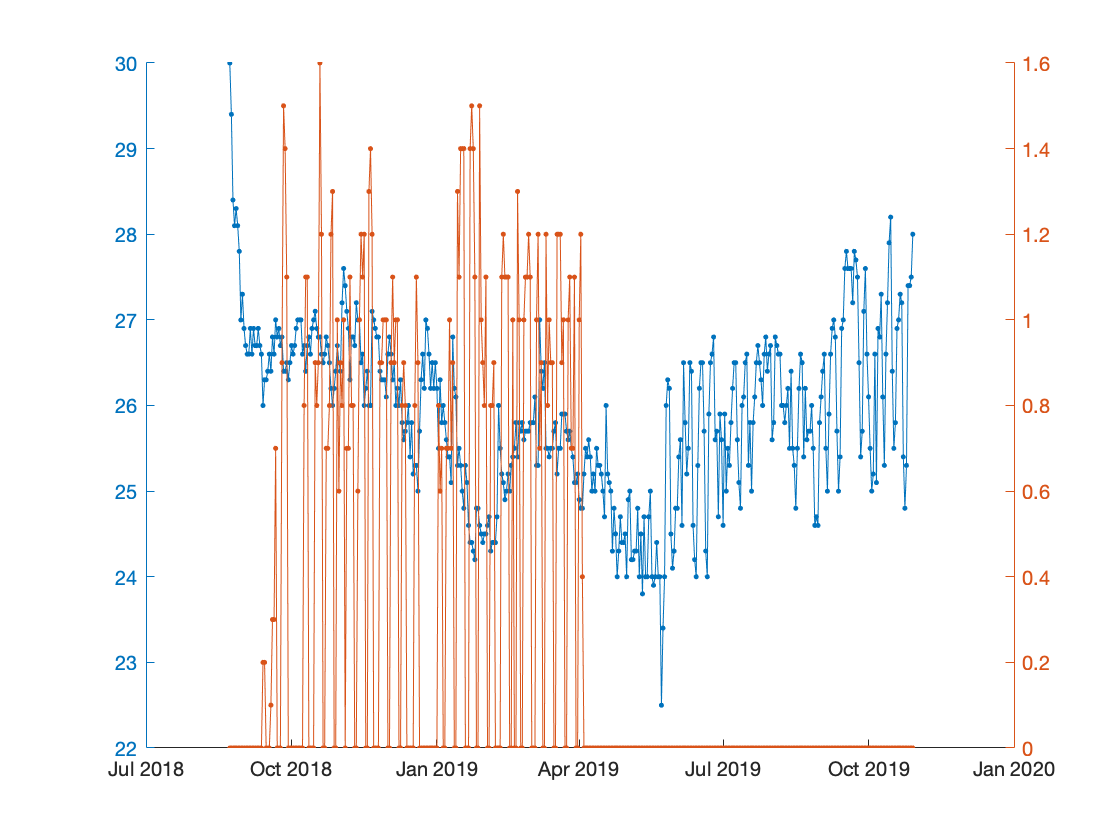

figure; hold on
yyaxis left
plot(weighing_date, weight, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Performance as a function of date

acquisition.Session

acquisition.Session & subj_key

Plot performance as a function of date.

[session_date, performance] = fetchn(acquisition.Session & subj_key, 'session_date', 'session_performance');
session_date = datetime(session_date);
figure; plot(session_date, performance, '.-')

Plot both performance and earned water as a function of date.

figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Compute trial numbers of a given date.

behavior.TowersBlockTrial & subj & 'session_date="2018-09-20"'

Compute trial numbers of each date

query = acquisition.Session & subj_key
[session_date, n_trials] = fetchn(query.aggr(behavior.TowersBlockTrial, 'count(*) -> n'), 'session_date', 'n');
session_date = datetime(session_date);
figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

## Summary

In session 1, we have covered basic methods to explore, browse and fetch data from the data pipeline. In the next session, we will learn how to generate different kinds of tables, ingest, delete, and compute entries.